% coeff = pca(X) 返回 n×p 数据矩阵 X 的主成分系数，也称为载荷。
% X 的行对应于观测值，列对应于变量。系数矩阵是 p×p 矩阵。

% coeff 的每列包含一个主成分的系数，并且这些列按成分方差的降序排列。
% 默认情况下，pca 将数据中心化，并使用奇异值分解 (SVD) 算法。
 
clear all
%  Step 1
%  加载样本数据集。
load hald

% Step 2
% 原料数据有 4 个变量的 13 个观测值。
% 找出原料数据的主成分。

 [coeff,score,latent,tsquared,explained] = pca(ingredients)

coeff =    -0.0678   -0.6460    0.5673    0.5062
   -0.6785   -0.0200   -0.5440    0.4933
    0.0290    0.7553    0.4036    0.5156
    0.7309   -0.1085   -0.4684    0.4844


score =    36.8218   -6.8709   -4.5909    0.3967
   29.6073    4.6109   -2.2476   -0.3958
  -12.9818   -4.2049    0.9022   -1.1261
   23.7147   -6.6341    1.8547   -0.3786
   -0.5532   -4.4617   -6.0874    0.1424
  -10.8125   -3.6466    0.9130   -0.1350
  -32.5882    8.9798   -1.6063    0.0818
   22.6064   10.7259    3.2365    0.3243
   -9.2626    8.9854   -0.0169   -0.5437
   -3.2840  -14.1573    7.0465    0.3405


latent =   517.7969
   67.4964
   12.4054
    0.2372


tsquared =     5.6803
    3.0758
    6.0002
    2.6198
    3.3681
    0.5668
    3.4818
    3.9794
    2.6086
    7.4818


explained =    86.5974
   11.2882
    2.0747
    0.0397


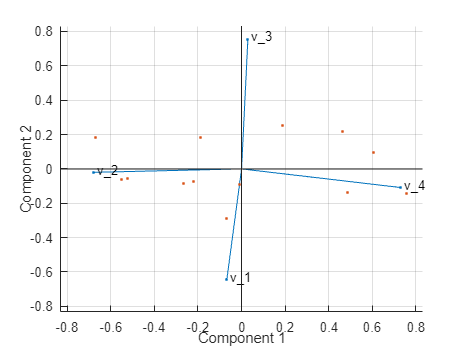

 
%  coeff 的行包含四个原料变量的系数，其列对应于四个主成分。

% Step3  画图（载荷图和得分图合二为一）
biplot(coeff(:,1:2),'scores',score(:,1:2),'varlabels',{'v_1','v_2','v_3','v_4'});

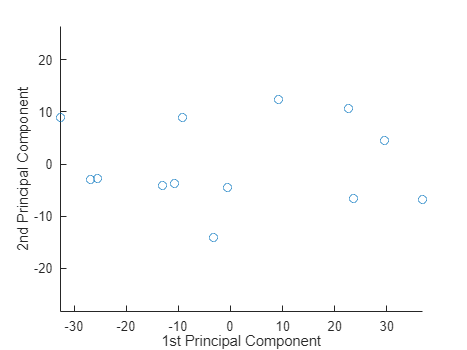


% Step4  画图： 前两个主成份下的散点图（得分图）
figure;
scatter(score(:,1),score(:,2))
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')